- Run preprocess_data.m first, this will take raw trajectory data, filter it, store secondary measures, such as speed, turn rates, times, etc. into separate files, all in the subject's folder for later analysis

- Run plot_traj.m next. This will plot the data for visual analysis

- Run this file next

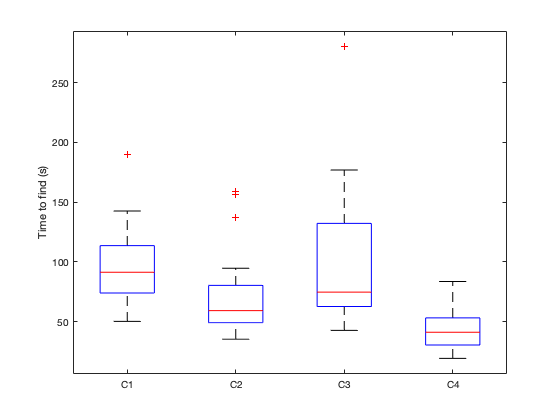

% time to find
timeArray = csvread('stats data/timeData.csv');
t_time = array2table(timeArray,...
    'VariableNames',{'C1','C2','C3','C4','SQ1','SQ2','SQ3','SQ4','SQ5'});
time_bp=boxplot(table2array(t_time(:,1:4)), 'labels', {'C1','C2','C3','C4'});
ylabel('Time to find (s)')

% -- define the measurements within the subjects (will  be used for all, for right now)
within=array2table([1 2 3 4]', 'variablenames', {'cond'});
rm_time=fitrm(t_time,'C1-C4~1', 'WithinDesign', within);
stats_time = ranova(rm_time)

stats_time = 2×8 table
                        SumSq    DF    MeanSq      F         pValue      pValueGG      pValueHF     pValueLB 
                        _____    __    ______    ______    __________    _________    __________    _________

    (Intercept):cond    47697     3     15899    14.022    3.1085e-07    8.818e-06    3.4188e-06    0.0010583
    Error(cond)         78235    69    1133.8                                                                


if stats_time.pValue(1) < 0.05
    res_time=multcompare(rm_time, 'cond', 'ComparisonType','bonferroni')
end

res_time = 12×7 table
    cond_1    cond_2    Difference    StdErr      pValue       Lower      Upper 
    ______    ______    __________    ______    __________    _______    _______

      1         2         25.873      7.5925      0.014476     3.9595     47.787
      1         3        -1.5769      11.759             1    -35.517     32.363
      1         4         53.002      7.7561    3.4359e-06     30.616     75.388
      2         1        -25.873      7.5925      0.014476    -47.787    -3.9595
      2         3         -27.45      11.796       0.17473    -61.496     6.5956
      2         4         27.129       6.607     0.0025929     8.0592     46.198
      3         1         1.5769      11.759             1    -32.363     35.517
      3   

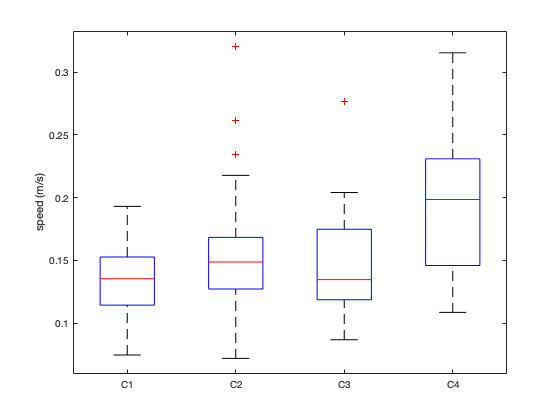



% speed
EKFSpdData = csvread('stats data/EKFVelData.csv');
t_EKFSpd = array2table(EKFSpdData,...
    'VariableNames',{'C1','C2','C3','C4','SQ1','SQ2','SQ3','SQ4','SQ5'});
EKFSpd_bp = boxplot(table2array(t_EKFSpd(:,1:4)), 'labels', {'C1','C2','C3','C4'});
ylabel('speed (m/s)')

rm_EKFSpd=fitrm(t_EKFSpd,'C1-C4~1', 'WithinDesign', within);
stats_EKFSpd = ranova(rm_EKFSpd)

stats_EKFSpd = 2×8 table
                         SumSq      DF     MeanSq        F         pValue       pValueGG      pValueHF     pValueLB 
                        ________    __    _________    ______    __________    __________    __________    _________

    (Intercept):cond    0.060588     3     0.020196    12.472    1.3135e-06    3.3936e-06    1.3135e-06    0.0017851
    Error(cond)          0.11173    69    0.0016193                                                                 


if stats_EKFSpd.pValue(1) < 0.05
    res_EKFSpd=multcompare(rm_EKFSpd, 'cond', 'ComparisonType','bonferroni')
end

res_EKFSpd = 12×7 table
    cond_1    cond_2    Difference     StdErr        pValue        Lower         Upper   
    ______    ______    __________    _________    __________    __________    __________

      1         2       -0.023475     0.0095614        0.1324     -0.051071     0.0041222
      1         3       -0.013293       0.01075             1     -0.044321      0.017735
      1         4       -0.066996      0.011101    2.2365e-05     -0.099035     -0.034957
      2         1        0.023475     0.0095614        0.1324    -0.0041222      0.051071
      2         3        0.010182      0.013065             1     -0.027528      0.047891
      2         4       -0.043521      0.012696      0.013788     -0.080166    -0.0068761
      3         1

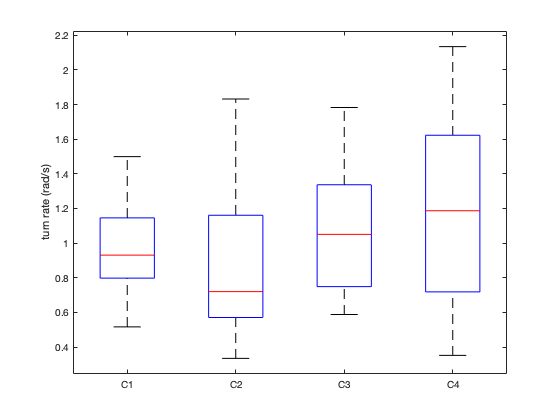



% turn rate
EKFOmegaArray = csvread('stats data/EKFOmegaData.csv');
t_EKFOmega = array2table(EKFOmegaArray,...
    'VariableNames',{'C1','C2','C3','C4','SQ1','SQ2','SQ3','SQ4','SQ5'});
EKFOmega_bp = boxplot(table2array(t_EKFOmega(:,1:4)), 'labels', {'C1','C2','C3','C4'});
ylabel('turn rate (rad/s)')

rm_EKFOmega=fitrm(t_EKFOmega,'C1-C4~1', 'WithinDesign', within);
stats_EKFOmega = ranova(rm_EKFOmega)

stats_EKFOmega = 2×8 table
                        SumSq     DF    MeanSq       F        pValue     pValueGG    pValueHF    pValueLB
                        ______    __    _______    ______    ________    ________    ________    ________

    (Intercept):cond     1.176     3    0.39201    2.4651    0.069536    0.085675    0.078066    0.13006 
    Error(cond)         10.973    69    0.15903                                                          


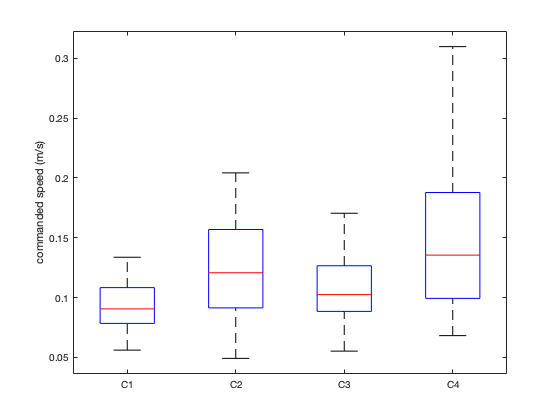

if stats_EKFOmega.pValue(1) < 0.05
    res_EKFOmega=multcompare(rm_EKFOmega, 'cond', 'ComparisonType','bonferroni')
end

% commanded speed
comSpeedArray = csvread('stats data/VelData.csv');
t_comSpeed = array2table(comSpeedArray,...
    'VariableNames',{'C1','C2','C3','C4','SQ1','SQ2','SQ3','SQ4','SQ5'});
comSpeed_bp = boxplot(table2array(t_comSpeed(:,1:4)), 'labels', {'C1','C2','C3','C4'});
ylabel('commanded speed (m/s)')

rm_comSpeed=fitrm(t_comSpeed,'C1-C4~1', 'WithinDesign', within);
stats_comSpeed = ranova(rm_comSpeed)

stats_comSpeed = 2×8 table
                         SumSq      DF     MeanSq        F         pValue       pValueGG      pValueHF     pValueLB 
                        ________    __    _________    ______    __________    __________    __________    _________

    (Intercept):cond    0.043499     3       0.0145    11.547    3.1938e-06    8.9677e-05    4.8125e-05    0.0024701
    Error(cond)         0.086645    69    0.0012557                                                                 


if stats_comSpeed.pValue(1) < 0.05
    res_comSpeed=multcompare(rm_comSpeed, 'cond', 'ComparisonType','bonferroni')
end

res_comSpeed = 12×7 table
    cond_1    cond_2    Difference     StdErr       pValue        Lower         Upper   
    ______    ______    __________    _________    _________    __________    __________

      1         2        -0.03029     0.0075266    0.0031763     -0.052014    -0.0085667
      1         3       -0.012436     0.0060505      0.30817       -0.0299     0.0050269
      1         4        -0.05665      0.012784    0.0011526     -0.093548     -0.019752
      2         1         0.03029     0.0075266    0.0031763     0.0085667      0.052014
      2         3        0.017854     0.0082034      0.24027    -0.0058232      0.041531
      2         4        -0.02636      0.012603      0.28629     -0.062735      0.010016
      3         1      

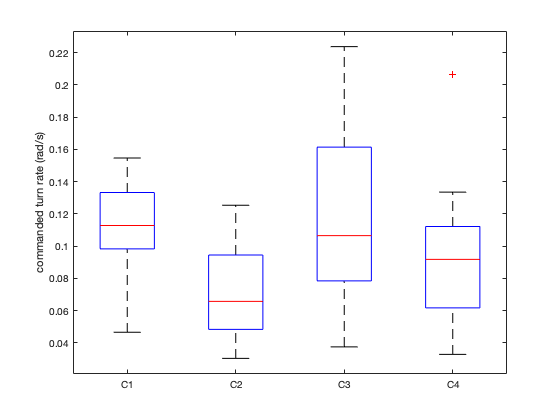



% commanded turn rate
comTurnRateArray = csvread('stats data/OmegaData.csv');
t_comTurnRate = array2table(comTurnRateArray,...
    'VariableNames',{'C1','C2','C3','C4','SQ1','SQ2','SQ3','SQ4','SQ5'});
comTurnRate_bp = boxplot(table2array(t_comTurnRate(:,1:4)), 'labels', {'C1','C2','C3','C4'});
ylabel('commanded turn rate (rad/s)')

rm_comTurnRate=fitrm(t_comTurnRate,'C1-C4~1', 'WithinDesign', within);
stats_comTurnRate = ranova(rm_comTurnRate)

stats_comTurnRate = 2×8 table
                         SumSq      DF      MeanSq        F         pValue       pValueGG      pValueHF     pValueLB 
                        ________    __    __________    ______    __________    __________    __________    _________

    (Intercept):cond    0.029582     3     0.0098608    11.462    3.4691e-06    2.0171e-05    7.1614e-06    0.0025462
    Error(cond)         0.059362    69    0.00086031                                                                 


if stats_comTurnRate.pValue(1) < 0.05
    res_comTurnRate=multcompare(rm_comTurnRate, 'cond', 'ComparisonType','bonferroni')
end

res_comTurnRate = 12×7 table
    cond_1    cond_2    Difference     StdErr        pValue         Lower         Upper   
    ______    ______    __________    _________    __________    ___________    __________

      1         2         0.039754    0.0066371    2.4954e-05       0.020597       0.05891
      1         3       -0.0035671    0.0086396             1      -0.028503      0.021369
      1         4          0.02213    0.0077388      0.053191    -0.00020667      0.044466
      2         1        -0.039754    0.0066371    2.4954e-05       -0.05891     -0.020597
      2         3        -0.043321     0.009678     0.0010306      -0.071254     -0.015387
      2         4        -0.017624    0.0071001       0.12476      -0.038117     0.0028689
    



% 
% % -- display all tables that contain the data from the input, tracker and
% % -- the questionnaires
% % t_time
% % t_Vel
% % t_EKFSpd
% % t_Omega
% % t_EKFOmega
% 
% % -- create box plots for each of the tables, solely looking at conditions 1-4
% % -- all at the same time
% 
% 
% 
% 
% % -- apply the within to the data to get the rm
% % -- for right now solely look at conditions 1-4 without the questions
% 
% 
% % -- display the repeated measures for all data
% rm_time
% rm_Vel
% rm_EKFSpd
% rm_Omega
% rm_EKFOmega
% 
% % -- after running the fit rm function, run the stats function and display it
% 
% 
% % -- check if the stats p value is below 0.05, if it is, display the
% % -- pairwise comparisons
% 




% 